clear, close all, clc

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


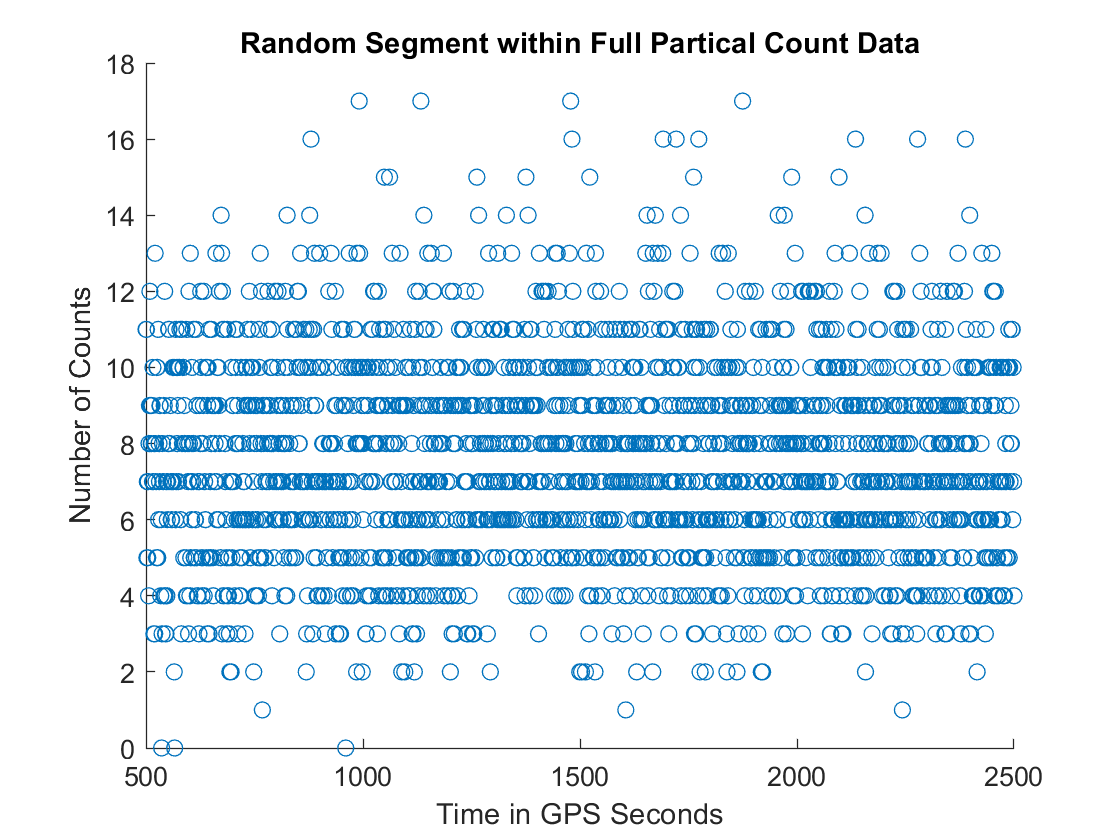


mydata = h5read("gammaray_lab4.h5",'/data');

x1 = mydata(:,4); %Partical Counts
x2 = mydata(:,3); %Earth Longitude
x3 = mydata(:,2); %Solar Phase
x4 = mydata(:,1); %Time

plot_scat([500,2000],x1)
title('Random Segment within Full Partical Count Data')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

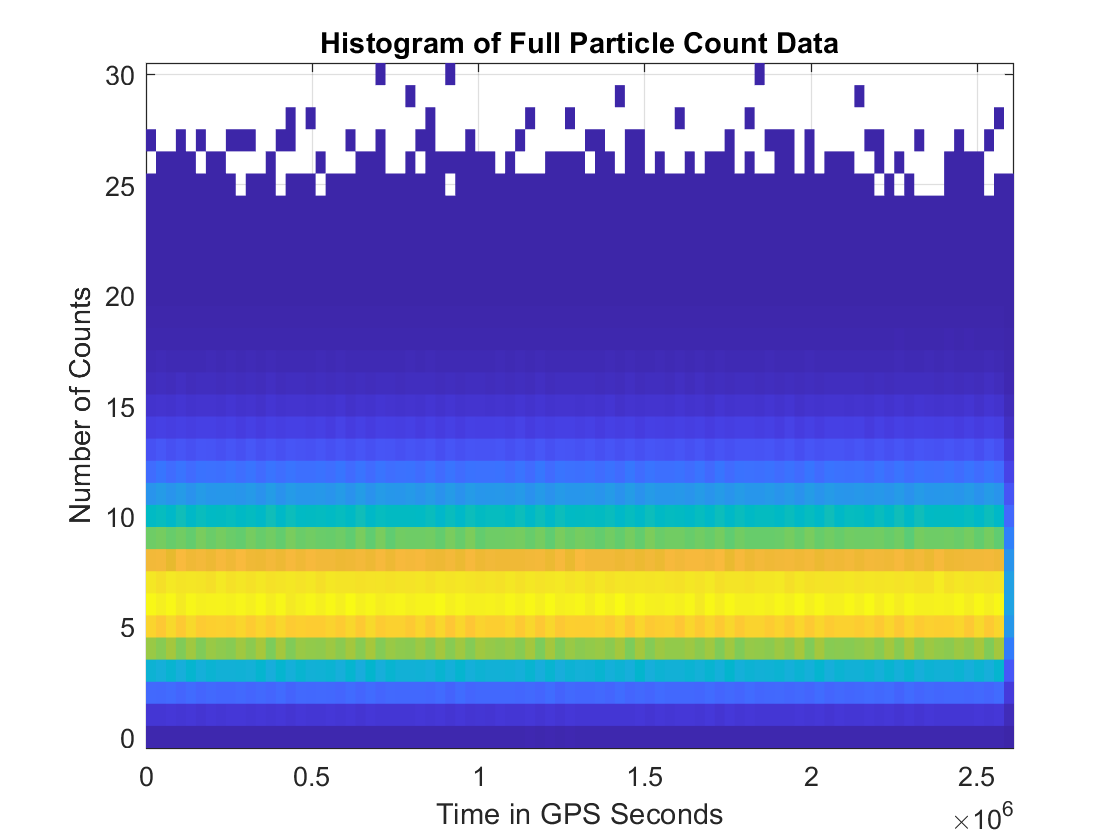


t = linspace(1,2592000,length(x1))';
histogram2(t,x1,'DisplayStyle', 'tile')
title('Histogram of Full Particle Count Data')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

At a high level the average number or particle counts per 0.1 seconds seems to be around 6. We can see from plotting the partical count against the longitudinal position of the SC that the background exponentially decays to around 5. In order to make a background pdf I will make the mean exponentially decay based initially on the logitudinal position which is based on time.

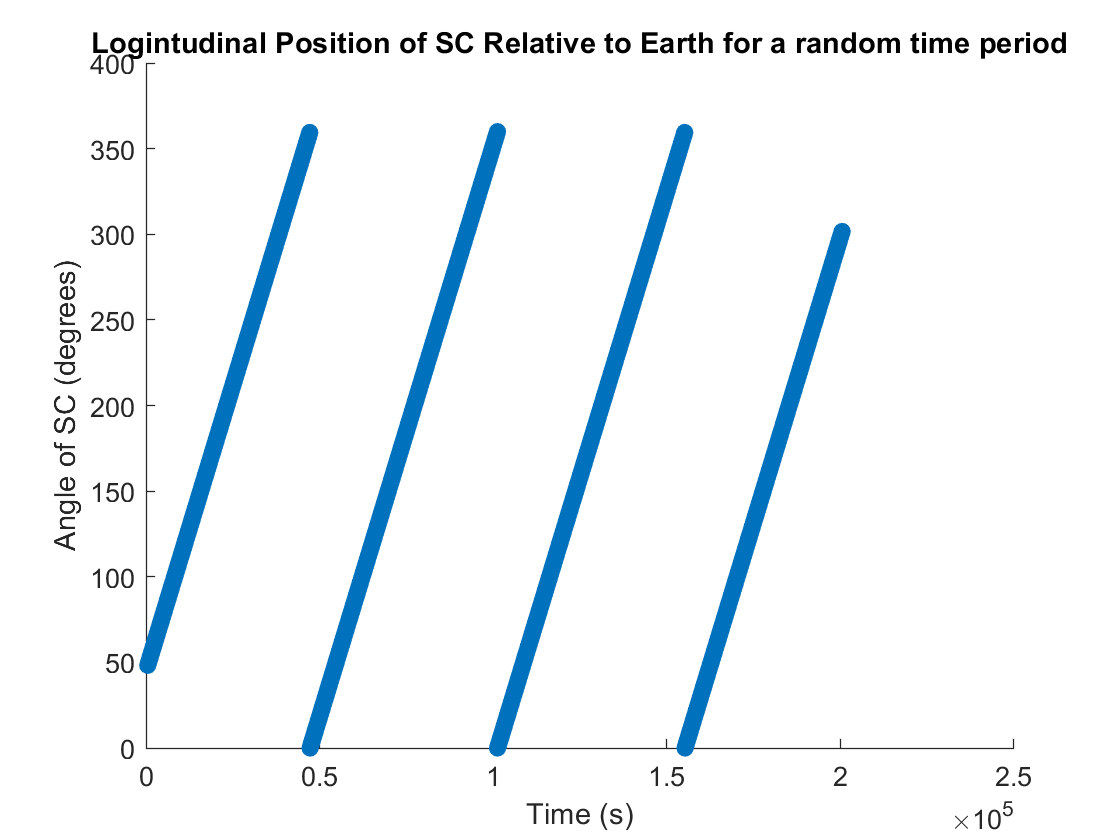

plot_scat([500,200000],x2)
title('Logintudinal Position of SC Relative to Earth for a random time period')
xlabel('Time (s)')
ylabel('Angle of SC (degrees)')

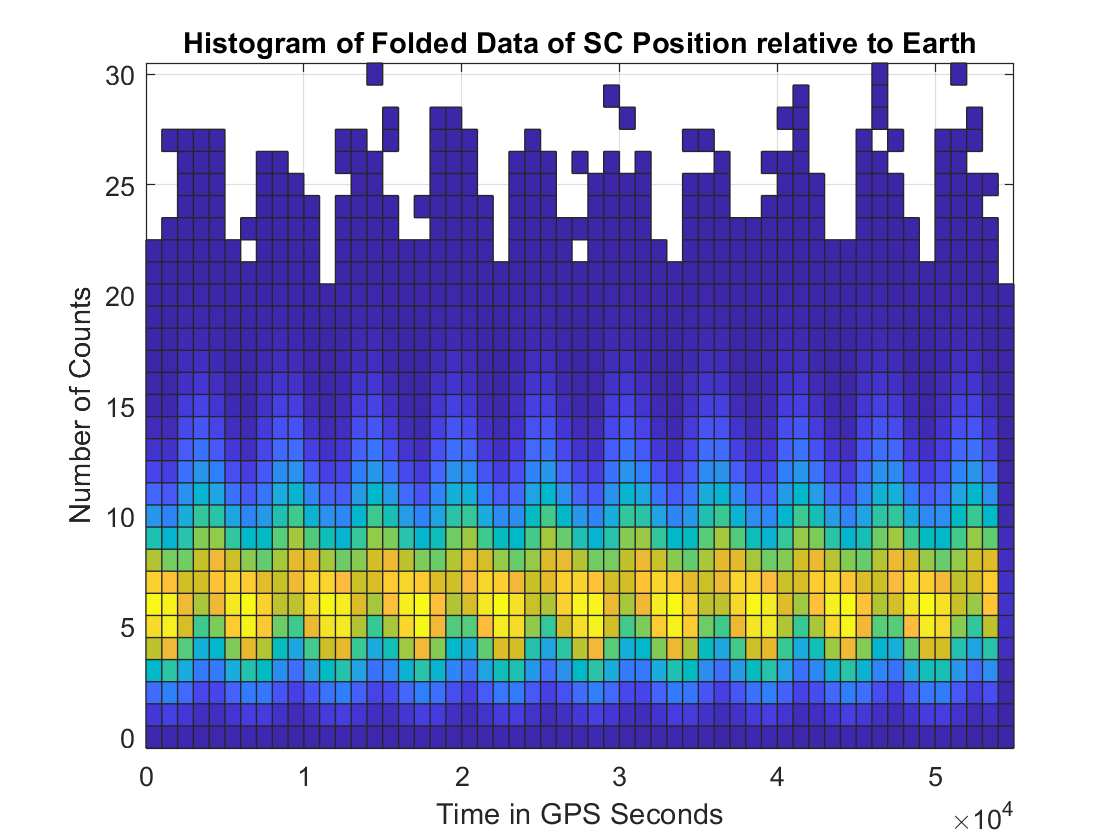


b1 = mod(t,54050);
histogram2(b1,x1,'DisplayStyle', 'tile')
title('Histogram of Folded Data of SC Position relative to Earth')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

Encountered some interresting almost sinusodial behavior in the plot to the right which I was not sure of the cause.

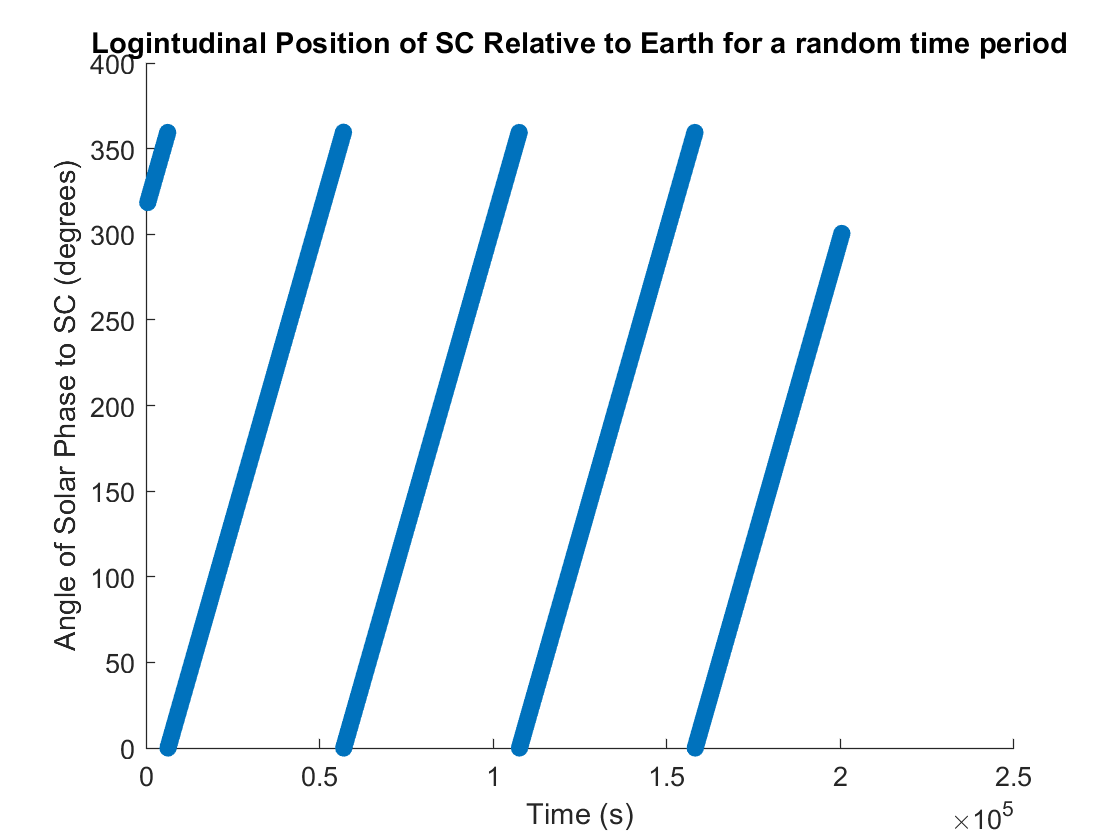

plot_scat([500,200000],x3)
title('Logintudinal Position of SC Relative to Earth for a random time period')
xlabel('Time (s)')
ylabel('Angle of Solar Phase to SC (degrees)')

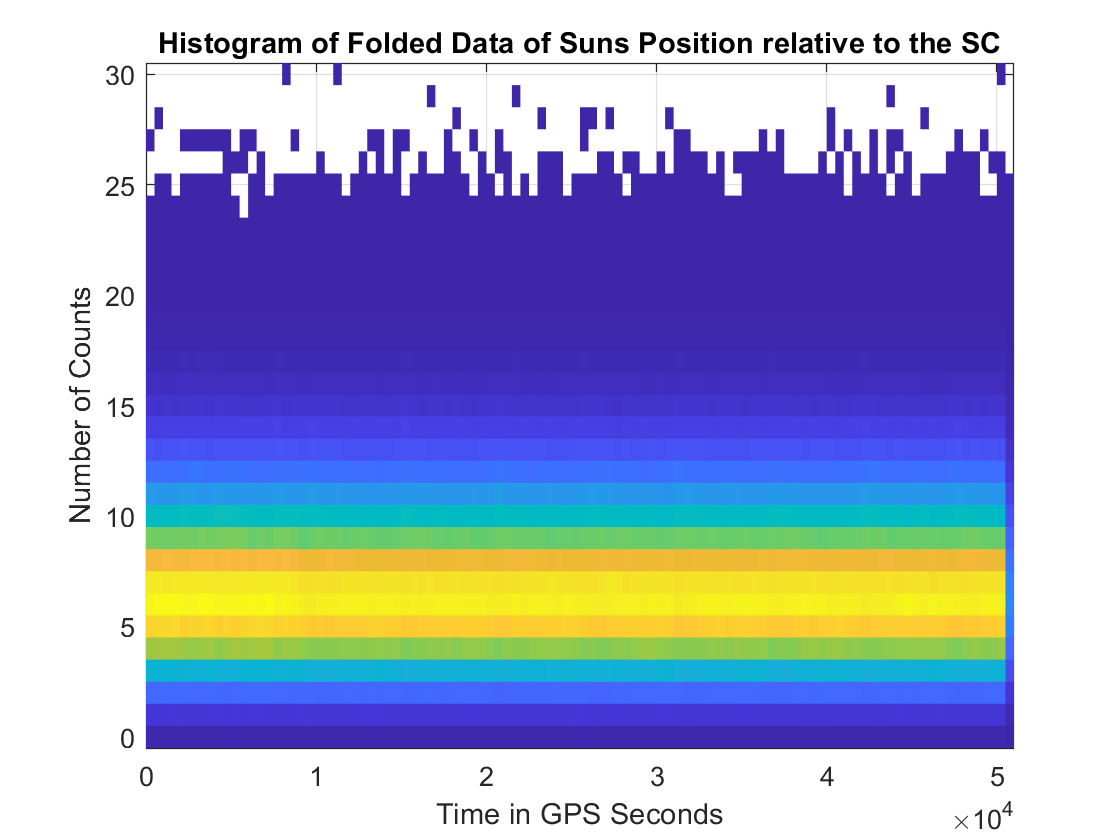


b2 = mod(t,50650);
histogram2(b2,x1,'DisplayStyle', 'tile')
title('Histogram of Folded Data of Suns Position relative to the SC')
xlabel('Time in GPS Seconds')
ylabel('Number of Counts')

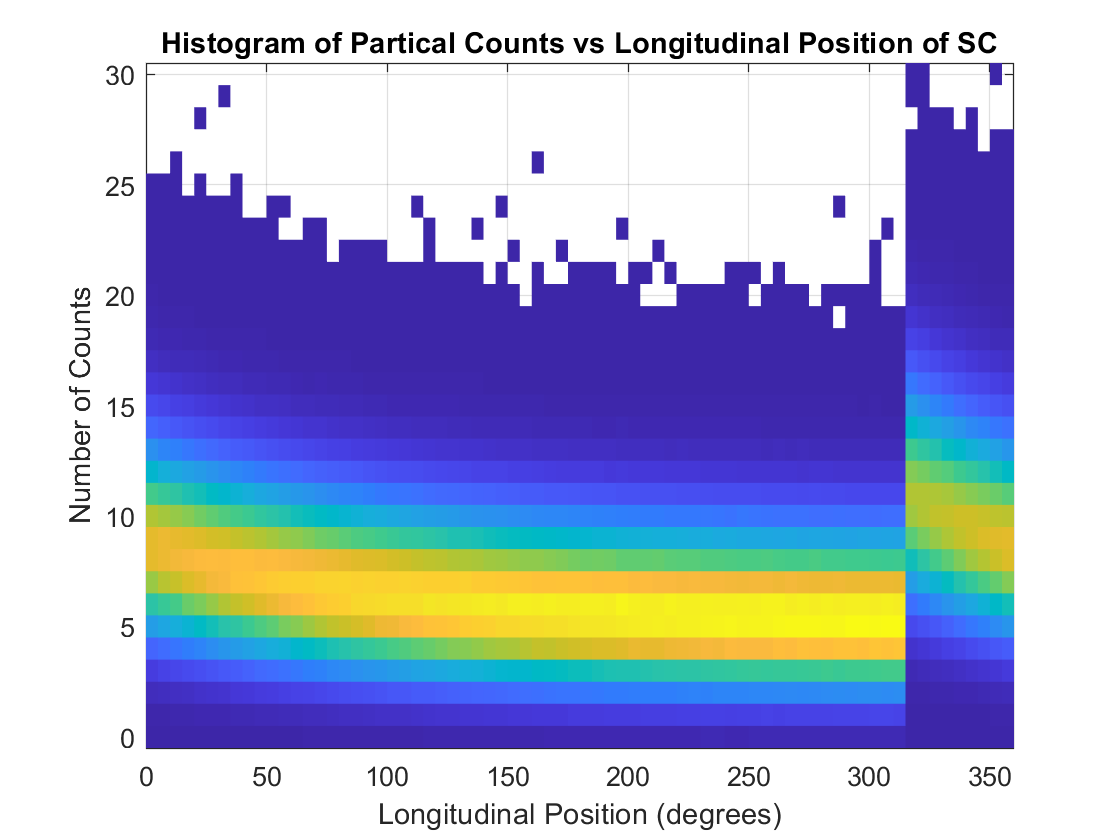


histogram2(x2,x1,'DisplayStyle', 'tile')
title('Histogram of Partical Counts vs Longitudinal Position of SC')
xlabel('Longitudinal Position (degrees)')
ylabel('Number of Counts')


for i = 1:length(x2)
    if x2(i) < 315
        x2(i) = x2(i)+360;
    end
end

histogram2(x2,x1,'DisplayStyle', 'tile')
title('Shifted Histogram of Partical Counts vs Longitudinal Position of SC')
xlabel('Longitudinal Position (degrees)')
ylabel('Number of Counts')
hold on

mean = @(t) (1/1.015).^(t-435)+5;
mean_curvefit = @(t) 17.81*exp(-0.001901*t);

scatter(x2,mean(x2),'Linewidth',4)


The exponential equation I used to model the mean is $mean(x) = \frac{1}{1.015}^{x-435}+5$ where $x=$logitudinal position of the SC relative to the earth. The longitudinal position is also based on time as the SC will need to be going a constant radial speed in order to maintain the same orbit. 

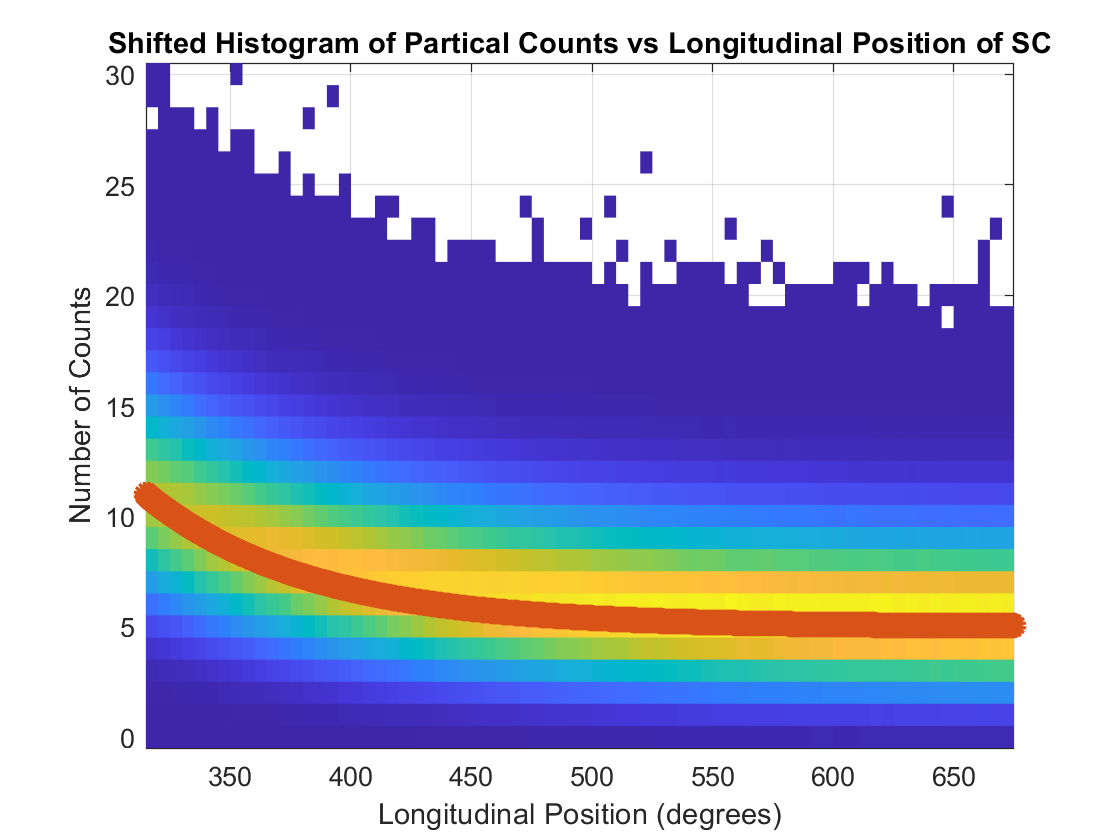

hold off

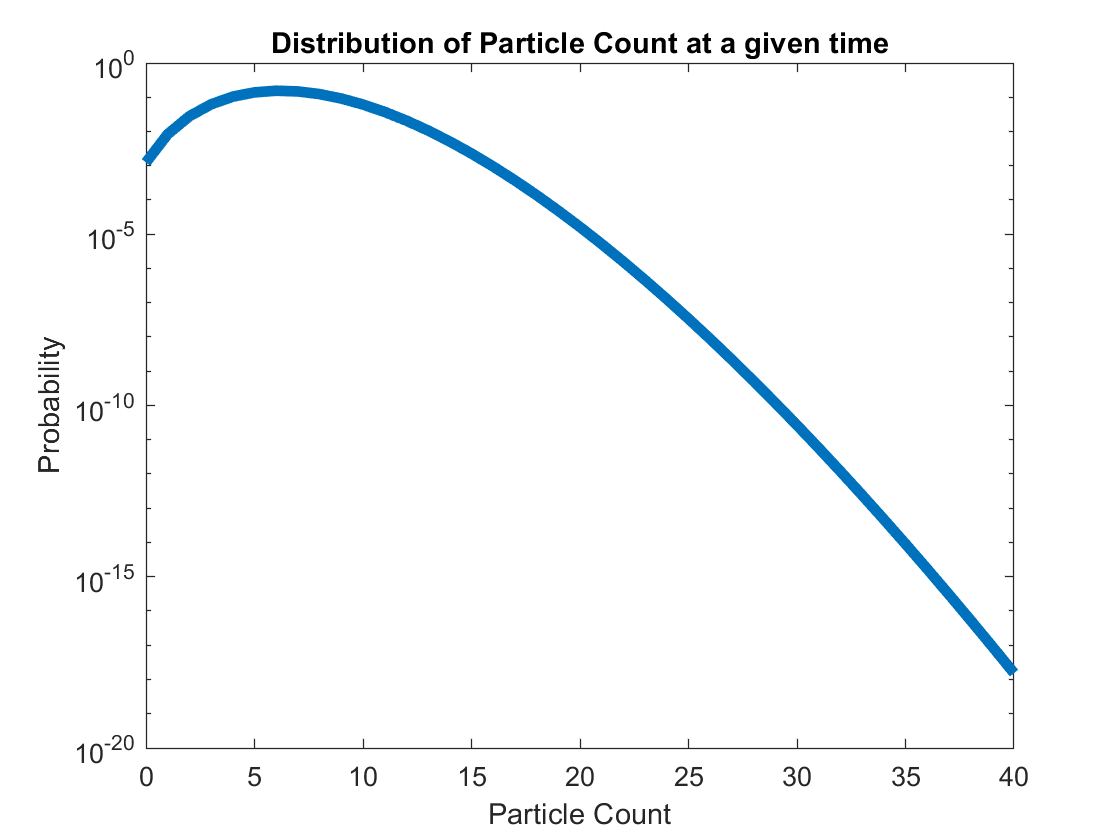

thresh1 =     24


long_val = 400; %choose a value in between 315 and 675
thresh1 = sig5thresh(long_val,mean)

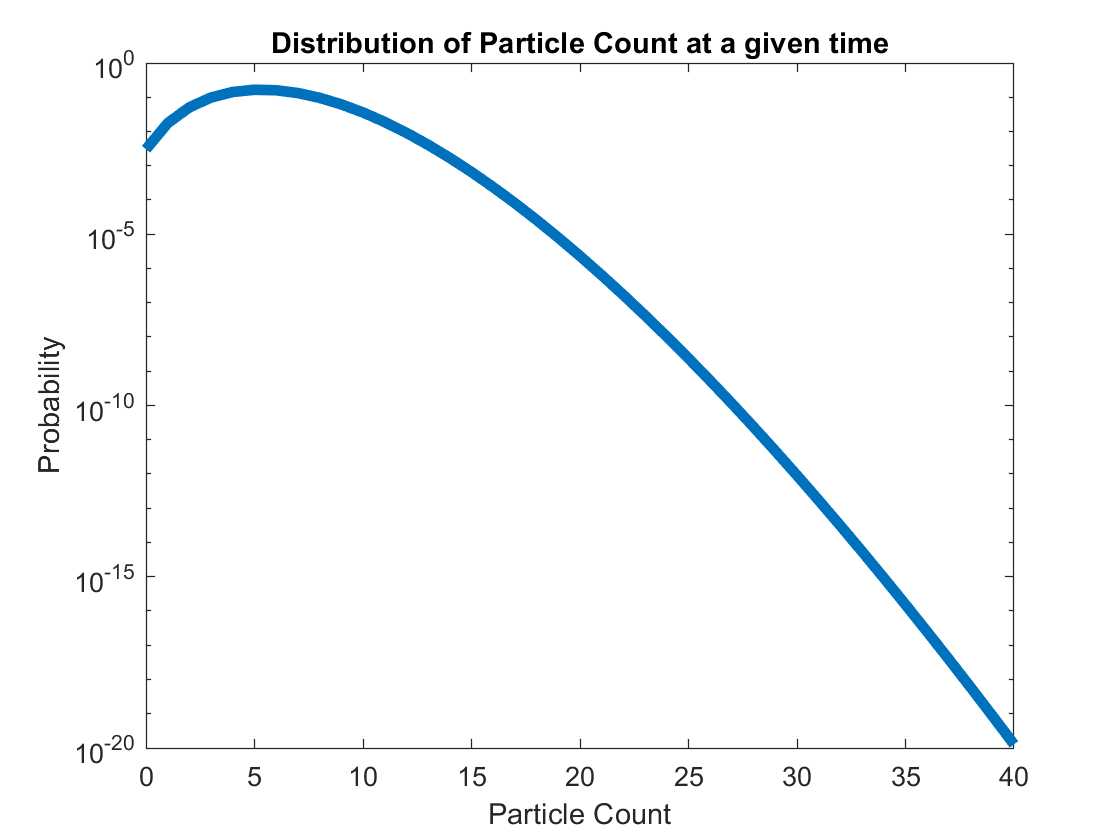

thresh2 =     22


long_val = 450;
thresh2 = sig5thresh(long_val,mean)

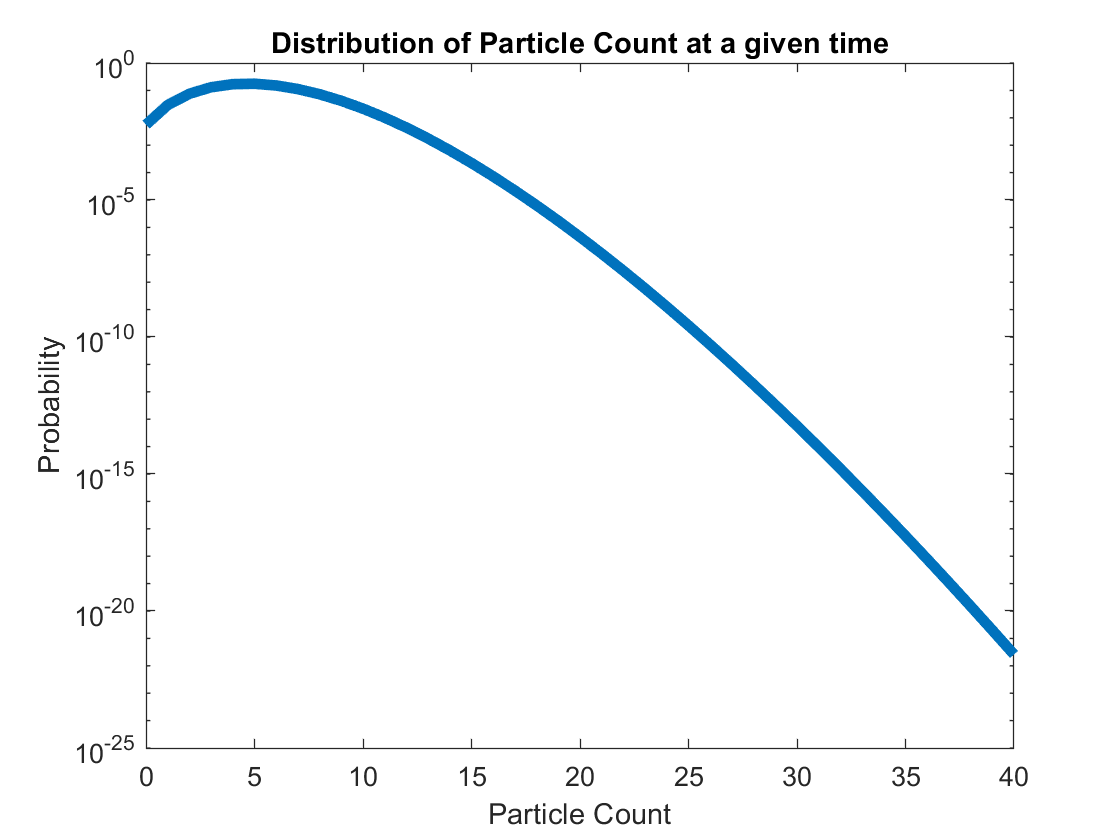

thresh3 =     21


long_val = 550;
thresh3 = sig5thresh(long_val,mean)

Using a Logitudinal positon of 400 degrees the SC would need to see a partical count of 24 in order to get into the 5 sigma realm. For 450 degrees it was 22 counts and then for 550 it was 21 counts.

## Problem 2

I will find the trainsient objects between images 1 and 3.

clear, close all, clc
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


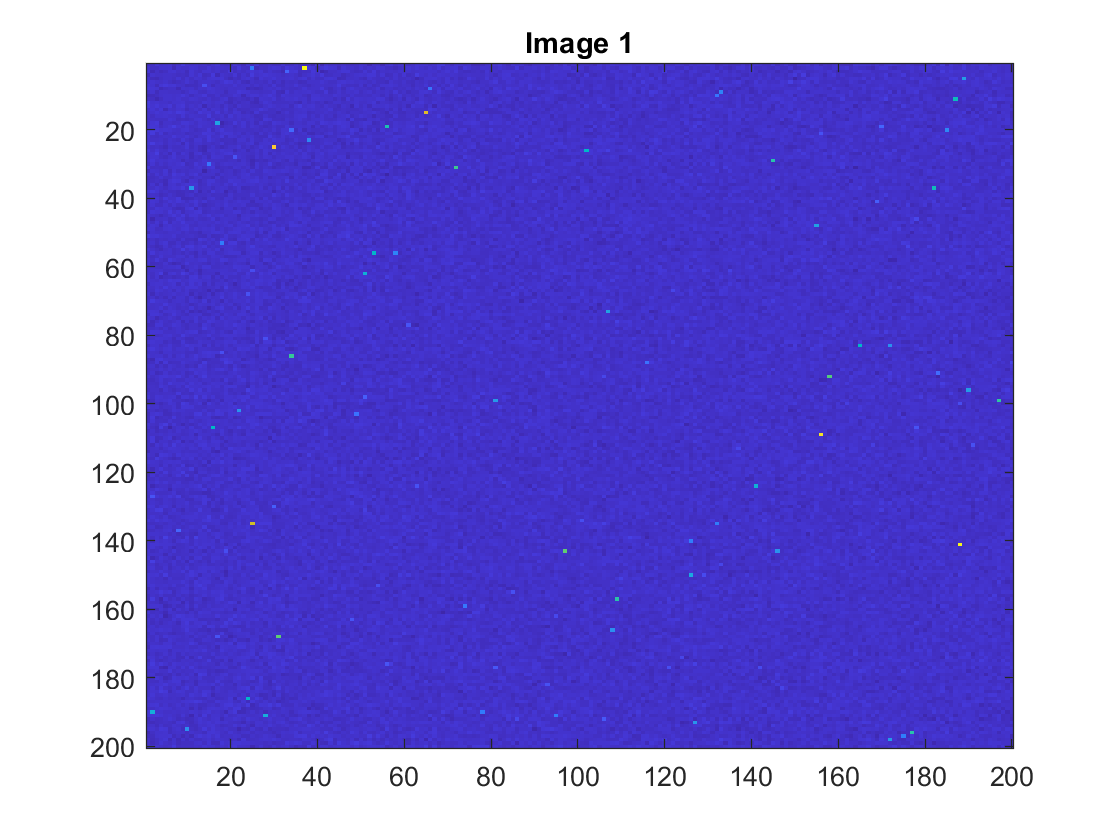

mydata = h5read("images.h5",'/imagestack');

image1 = mydata(1,1:200,1:200);
image1 = squeeze(image1);
image2 = mydata(2,1:200,1:200);
image2 = squeeze(image2);
image3 = mydata(3,1:200,1:200);
image3 = squeeze(image3);
image4 = mydata(4,1:200,1:200);
image4 = squeeze(image4);
image5 = mydata(5,1:200,1:200);
image5 = squeeze(image5);
image6 = mydata(6,1:200,1:200);
image6 = squeeze(image6);
image7 = mydata(7,1:200,1:200);
image7 = squeeze(image7);
image8 = mydata(8,1:200,1:200);
image8 = squeeze(image8);
image9 = mydata(9,1:200,1:200);
image9 = squeeze(image9);
image10 = mydata(10,1:200,1:200);
image10 = squeeze(image10);

imagesc(image1)
title('Image 1')

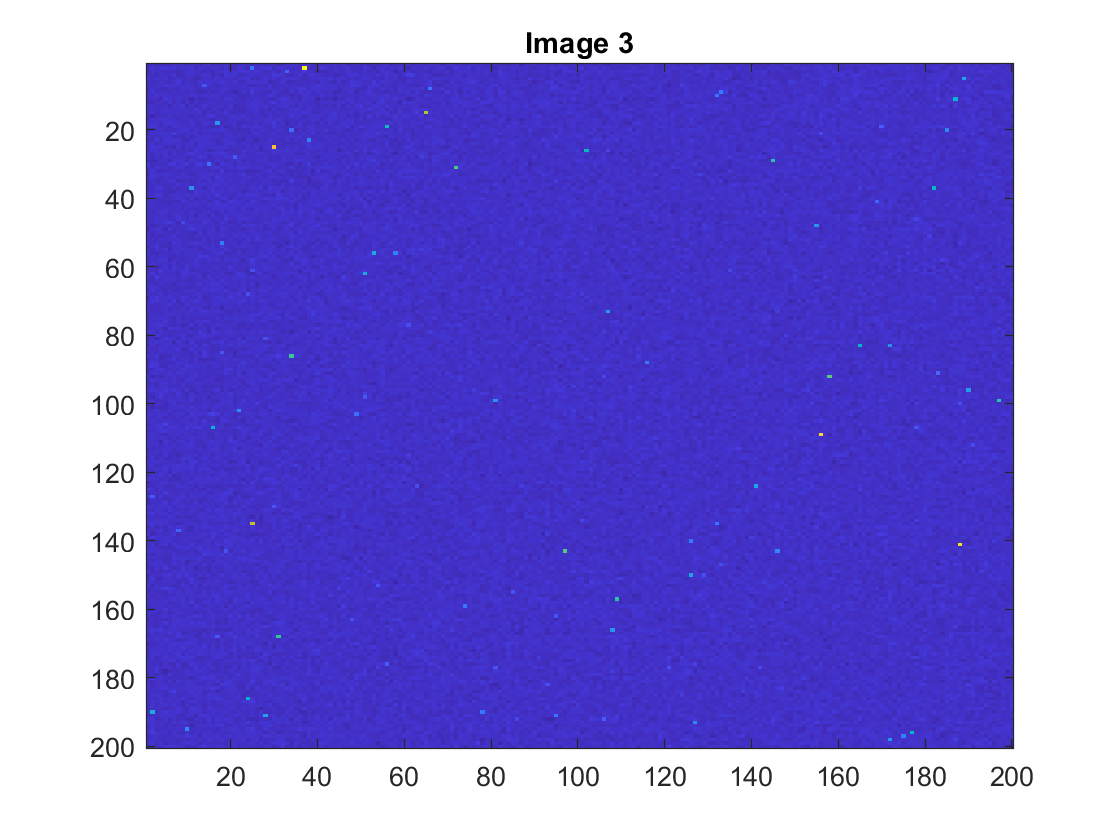

% imagesc(image2)
imagesc(image3)
title('Image 3')

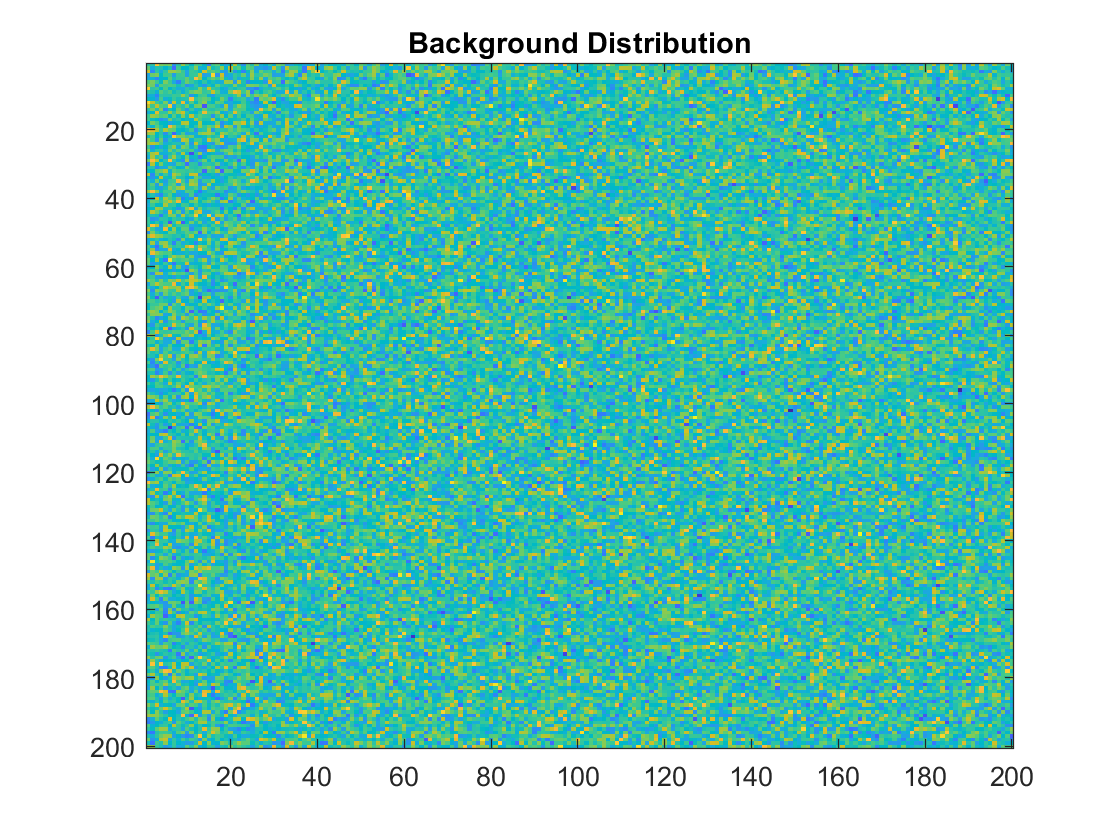

% imagesc(image4)
% imagesc(image5)
% imagesc(image6)
% imagesc(image7)
% imagesc(image8)
% imagesc(image9)
% imagesc(image10)

average = (image1+image2+image3+image4+image5+image6+image7+image8+image9+image10)./10;
imagesc(image1-image3)
title('Background Distribution')

histogram(image1-image3,40000)
hold on

sig =1;
mu = 0.1;
x = linspace(-4,4,1000);
gaus = makedist('Normal', mu,sig);
semilogy(x,21*pdf(gaus,x), 'Linewidth',4)
title('Histogram of Background Distribution with Fitted Gaussian')
xlabel('Pixel Value')
ylabel('Number of Occurences')

Looking at the images there does not appear to be any dependence on time. Nor signal contamination. In order to calculate a background PDF I will identify the two images that I wish to identify transients in. I will subtract them in order to give me a background distribution as shown in the histogram to the right. Since sigma is 1 lets airbitraily throw out values within 2.5 sigma in an effort to leave use with a signal.

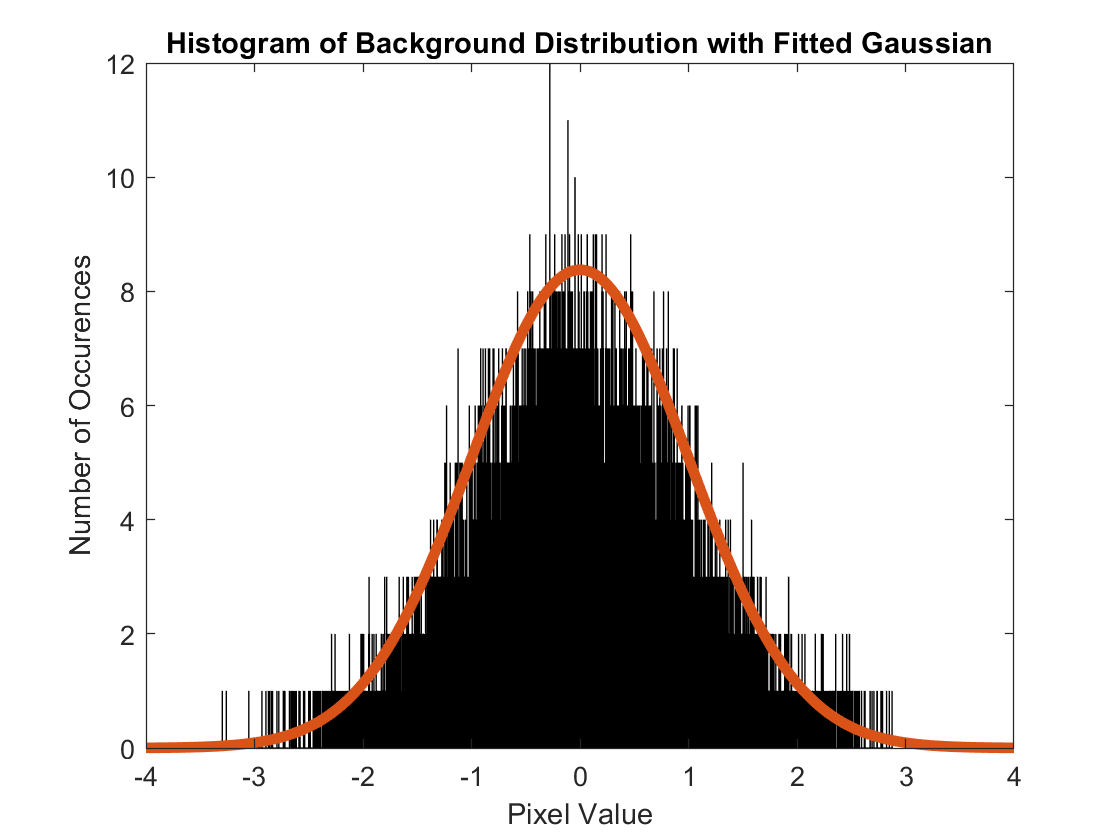

bkgnd_dist = image1-image3;
for i = 1:200
    for i2 = 1:200
        if bkgnd_dist(i,i2)<2.5 && bkgnd_dist(i,i2)>-2.5
            bkgnd_dist(i,i2) = NaN;
        end
    end
end
hold off

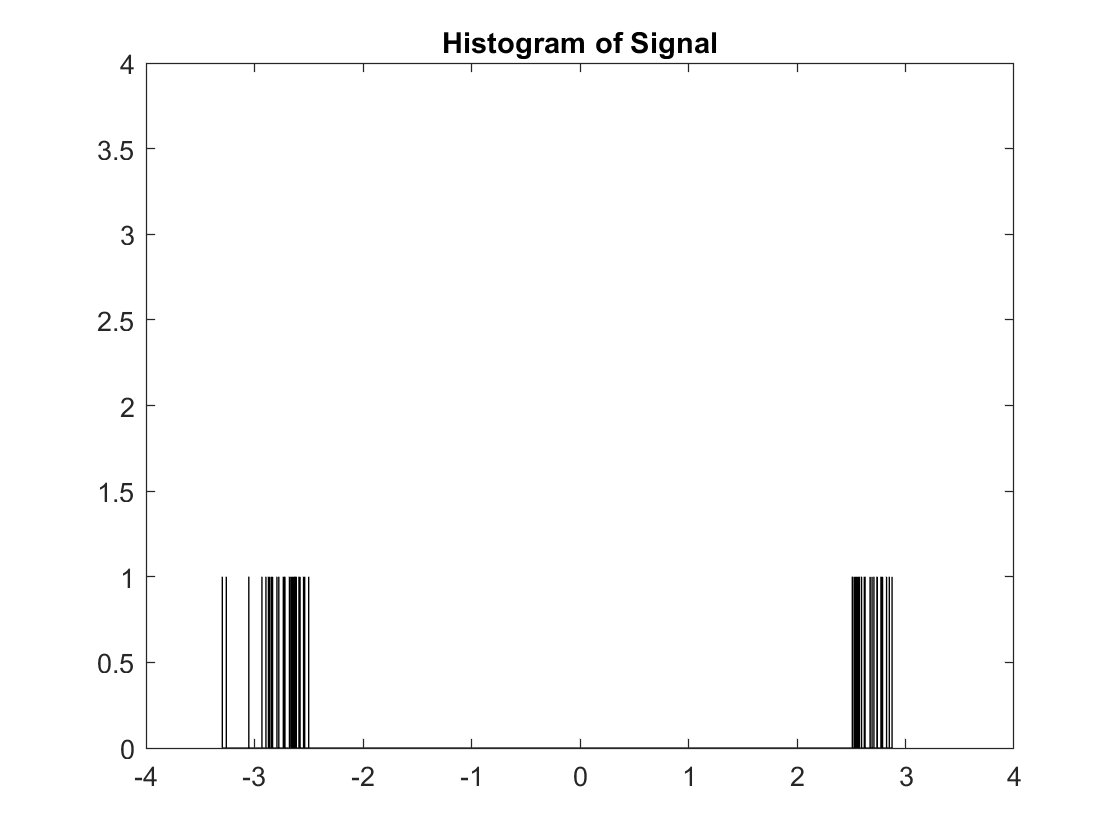

histogram(bkgnd_dist,40000)
title('Histogram of Signal')
ylim([0 4])
xlim([-4 4])

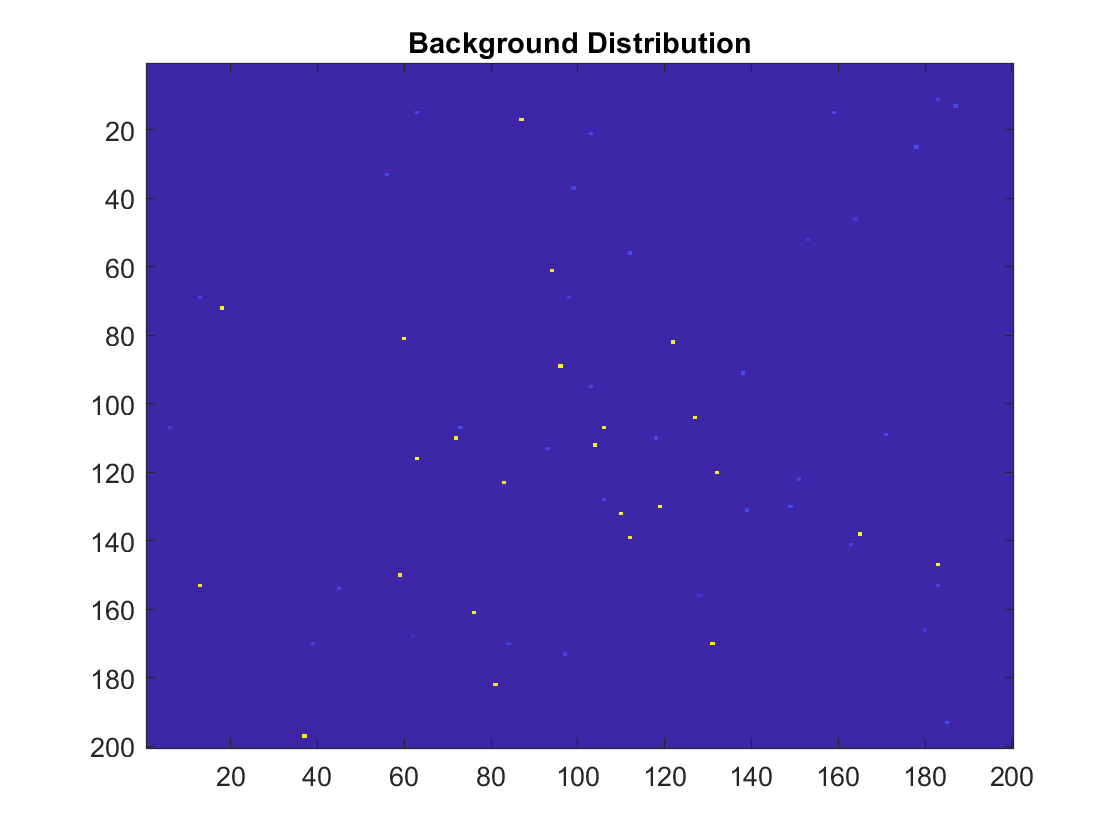

imagesc(bkgnd_dist)
title('Background Distribution')

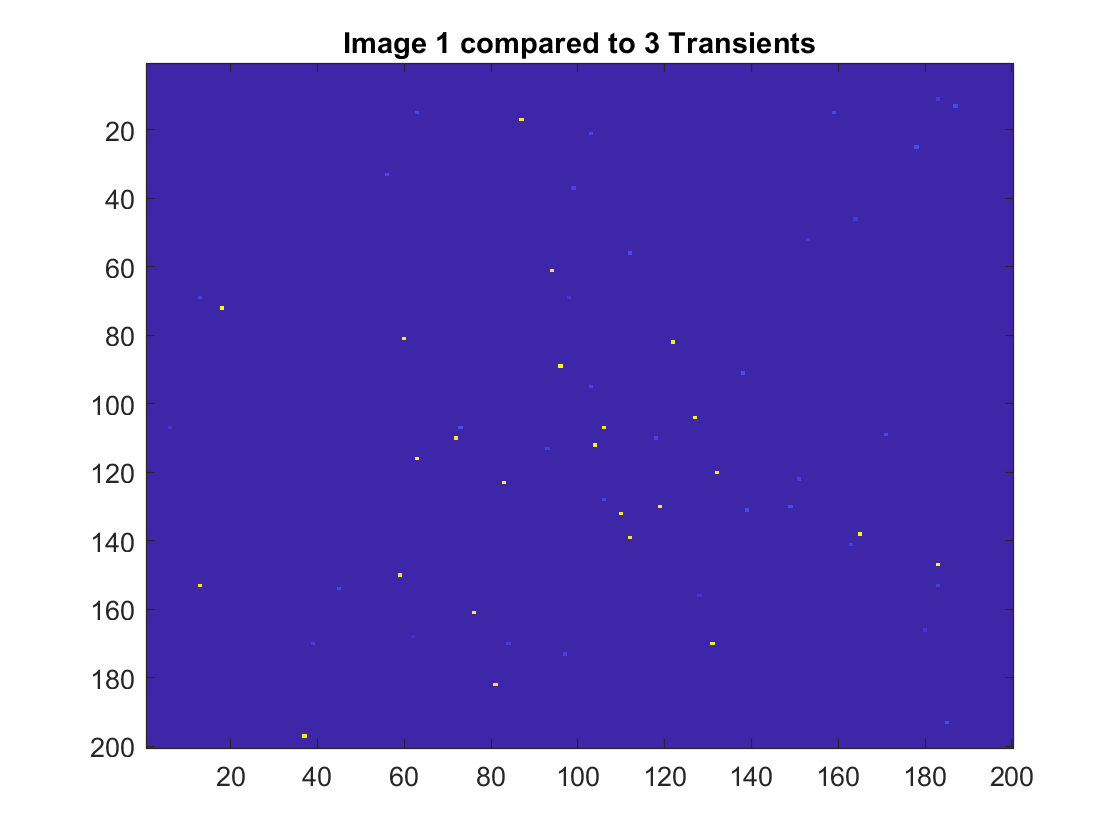

test = image1-bkgnd_dist;
test2 = image3-bkgnd_dist;
final = test-test2;
imagesc(final)
title('Image 1 compared to 3 Transients')

Every pixel that is yellow denotes a object that was present in the first image but not in the third and every pixel that is dark blue represents a object that was present in image 3 but not in image 1 to a 2.5 sigma certainty.

% hold off
% pixel1 = mydata(:,1,1);
% plot(pixel1,"LineWidth",4);
% xlabel('image')
% ylabel('Detection Value')
% title('1,1 Pixel Value across all images')
% pixel = zeros(10,1);
% step = 0;
% for i = 1:200
%     for i2 = 1:200
%         step = step + 1;
%         pixel(step,1:10) = mydata(:,i,i2);
%     end
% end
% hold off
% figure
% x_vals = ones(40000,10);
% for i = 1:40000
%     x_vals(i,1) = i;
%     x_vals(i,2) = i;
%     x_vals(i,3) = i;
%     x_vals(i,4) = i;
%     x_vals(i,5) = i;
%     x_vals(i,6) = i;
%     x_vals(i,7) = i;
%     x_vals(i,8) = i;
%     x_vals(i,9) = i;
%     x_vals(i,10) = i;
% end
% histogram2(x_vals,pixel(:,:),'DisplayStyle', 'tile');
% histogram2(ones(1,10),pixel(40,:),10,'DisplayStyle', 'tile');

function [] = plot_scat(range, x)
% range(start_val, length)
end_pnt = range(1)+range(2);
t = linspace(range(1),end_pnt, range(2));
scatter(t,x(range(1):range(1)+range(2)-1))
end

function [thresh] = sig5thresh(long_val,mean)
mean_val = mean(long_val);
x = 0:40;
poisson = makedist("Poisson", 'lambda',mean_val);
semilogy(x,pdf(poisson,x),"LineWidth",4);
title('Distribution of Particle Count at a given time')
xlabel('Particle Count')
ylabel('Probability')
prob5_sig = 1-3e-7;
y_vals = pdf(poisson,x);
for i = 1:length(x)
    check = sum(y_vals(1:i));
    if check > prob5_sig
        thresh = i;
        break
    end
end
end